# **youBot dynamic model**

## Robot dynamic model

If we consider the dynamic model of a rigid robot as described in Khalil 2002, Chapter 9, with $\mathit{\mathbf{M}}$ the mass-inertia matrix of the robot, $\mathit{\mathbf{h}}$ the vector regrouping velocities and accelerations related torques, $\tau_r \;\;\textrm{and}\;\tau_e$ respectively the robot control and environment torques.


$$\mathbf{M}(\mathbf{q})\ddot{\mathbf{q}} + \mathbf{h}(\dot{\mathbf{q}}, \mathbf{q}) = \mathbf{\tau}_r + \mathbf{\tau}_{e}$$


If we consider the force ${\mathit{\mathbf{f}}}_e$ that is applied by the environnement on the robot, the Coriolis and Centrifugal torques $\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)$, the viscous matrix ${\mathit{\mathbf{F}}}_v$, the static friction torques ${\mathit{\mathbf{f}}}_s$ and the gravity torque $\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)$, the dynamic equation can be explicited as follow:

 
$$\ddot{\mathit{\mathbf{q}}} ={M\left(\mathit{\mathbf{q}}\right)}^{-1} \left(\tau {\;}_r -{\nu \mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^t \;{\mathit{\mathbf{f}}}_e -{\mathit{\mathbf{F}}}_v \;\dot{\mathit{\mathbf{q}}\;} -{\mathit{\mathbf{f}}}_s \left(\dot{\mathit{\mathbf{q}}} \right)-\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)\dot{\mathit{\mathbf{q}}} -\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)\right)$$


% cleaning workspace variables
clear all
clc
addpath('dynamic_sim\')

% symbolic states
q = sym('q',[3 1]);
q'

$$ans = \left(\begin{array}{ccc} \bar{q_{1}} & \bar{q_{2}} & \bar{q_{3}} \end{array}\right)$$

dq = sym('dq',[3 1]);
dq'

$$ans = \left(\begin{array}{ccc} \bar{{\mathrm{dq}}_{1}} & \bar{{\mathrm{dq}}_{2}} & \bar{{\mathrm{dq}}_{3}} \end{array}\right)$$

fe = sym('fe',[3 1]);
fe'

$$ans = \left(\begin{array}{ccc} \bar{{\mathrm{fe}}_{1}} & \bar{{\mathrm{fe}}_{2}} & \bar{{\mathrm{fe}}_{3}} \end{array}\right)$$

Fv = diag([0.5,0.37,0.7]);                 % viscous matrix
J = J0E_3DOF(q(1),q(2),q(3));              % jacobian matrix
iM = iM_3DOF(q(2),q(3));                   % inverse mass-inertia matrix
Cor = C_3DOF(dq(1),dq(2),dq(3),q(2),q(3)); % Coriolis matrix
g = G_3DOF(q(1),q(2),q(3));                % gravity vector
Fs = diag([0.97571, 0.65131, 0.25819]);    % static friction matrix
fs = Fs*sign(dq);                          % static friction torques
nu = 0.65;                                 % transmission efficiency

## **Robot control**

Let's call ${\mathit{\mathbf{C}}}_v$ the joint velocity controler of the youBot drivers. It generates current setpoints, that can be converted to motor torques using the torque constants matrix ${\mathit{\mathbf{T}}}_c$, and then to joint torques with the gear ratios matrix $\mathit{\mathbf{R}}$, the inner current dynamics are neglected since their time response are in tenth of microseconds. Therefore, the torque setpoints are considered to be the actual robot torques:


$$\mathbf{\tau}_r \approx \mathbf{\tau}_d = \mathbf{R} \mathbf{T}_c \mathbf{i}_d  = \mathbf{R} \mathbf{T}_c \mathbf{C}_v \left( \dot{\mathbf{q}}_d - \dot{\mathbf{q}} \right) = \mathbf{R} \mathbf{T}_c  \left( \mathbf{K}_v \left( \dot{\mathbf{q}}_d - \dot{\mathbf{q}} \right) + \mathbf{K}_{vi} \int \left( \dot{\mathbf{q}}_d - \dot{\mathbf{q}} \right) \mathrm{d}t \right)$$


The joint velocity setpoint $\dot{{\mathit{\mathbf{q}}}_d }$ is obtained thanks to the cartesian admittance controler ${\mathit{\mathbf{C}}}_z$. The conversion from the cartesian to the joint space is done using the estimated inverse jacobian (in a known space where it is well defined).


$$\dot{\mathbf{q}}_d = \hat{\mathbf{J}}(\mathbf{q})^{-1} \mathbf{C}_z ( \mathbf{f}_e ) = \hat{\mathbf{J}}(\mathbf{q})^{-1} \left( \mathbf{K}_p \mathbf{f}_e + \mathbf{K}_{i} \int \mathbf{f}_e \,\mathrm{d}t \right)$$


% torque constants and gear ratios
Tc = diag([0.0335;0.0335;0.051]);
R = diag([156;100;71]);
% velocity control gains
Kv = diag([2500;1500;2000]./256)

Kv =     9.7656         0         0
         0    5.8594         0
         0         0    7.8125


Kvi = diag([3000;900;1000]./65536)

Kvi =     0.0458         0         0
         0    0.0137         0
         0         0    0.0153


% admittance control gains
cz = sym('cz',[2 1]);
Kp = diag([0, cz(1), 0]) % 0.015 in CASE (2020) paper

$$Kp = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & {\mathrm{cz}}_{1} & 0\\ 0 & 0 & 0 \end{array}\right)$$

Ki = diag([0, cz(2), 0]) % 0.080 in CASE (2020) paper

$$Ki = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & {\mathrm{cz}}_{2} & 0\\ 0 & 0 & 0 \end{array}\right)$$

% inverse Jacobian
iJ = iJ0E_3DOF(q(1),q(2),q(3));

## Linearisation

The dynamic equation is modeled for the cartesian acceleration $\ddot{\mathit{\mathbf{x}}}$ using the differential of the known (Khalil) relation between the joint velocity and the cartesian velocity. $\ddot{\mathit{\mathbf{x}}} =\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)\;\ddot{\mathit{\mathbf{q}}} +\dot{\mathit{\mathbf{J}}} \left(\mathit{\mathbf{q}}\right)\dot{\mathit{\mathbf{q}}}$


$$\ddot{\mathit{\mathbf{x}}} ={J\left(\mathit{\mathbf{q}}\right)M\left(\mathit{\mathbf{q}}\right)}^{-1} \left(\tau {\;}_r -{\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^t \;{\mathit{\mathbf{f}}}_e -{\mathit{\mathbf{F}}}_v \;\dot{\mathit{\mathbf{q}}\;} -{\mathit{\mathbf{f}}}_s \left(\dot{\mathit{\mathbf{q}}} \right)-\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)\dot{\mathit{\mathbf{q}}} -\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)\right)+\dot{\mathit{\mathbf{J}}} \left(\mathit{\mathbf{q}}\right)\dot{\mathit{\mathbf{q}}}$$


Then we can define a function ${\mathit{\mathbf{f}}}_1 :\mathit{\mathbf{q}}\;,\dot{\mathit{\mathbf{q}}} \;,\;{\mathit{\mathbf{f}}}_e \;,{\mathit{\mathbf{f}}}_e^{\prime } \;,{\mathit{\mathbf{f}}}_e^{\textrm{''}} \to \ddot{\mathit{\mathbf{x}}}$, with ${\mathit{\mathbf{f}}}_e^{\prime } \;,{\mathit{\mathbf{f}}}_e^{\textrm{''}}$ being respectively the integral and the double integral of the force.

We can also define a function $\mathit{\mathbf{f}}:\mathit{\mathbf{q}}\;,\;\dot{\mathit{\mathbf{q}}} \;,\;\;{\mathit{\mathbf{f}}}_e \;,\;{\mathit{\mathbf{f}}}_e^{\prime } \;,\;{\mathit{\mathbf{e}}}_v \to \ddot{\mathit{\mathbf{x}}}$, with the following definitions (to simplify the computation compared to the previous definition):


$${\mathit{\mathbf{e}}}_v =\int \dot{{\mathit{\mathbf{q}}}_d } \;-\dot{\mathit{\mathbf{q}}} \;\;\textrm{dt}$$



$${\mathit{\mathbf{f}}}_e^{\prime } =\int {\mathit{\mathbf{f}}}_e \;\;\textrm{dt}$$


% augmented symbolic states
ev = sym('ev',[3 1]);
ev'

$$ans = \left(\begin{array}{ccc} \bar{{\mathrm{ev}}_{1}} & \bar{{\mathrm{ev}}_{2}} & \bar{{\mathrm{ev}}_{3}} \end{array}\right)$$

ife = sym('ife',[3 1]);
ife'

$$ans = \left(\begin{array}{ccc} \bar{{\mathrm{ife}}_{1}} & \bar{{\mathrm{ife}}_{2}} & \bar{{\mathrm{ife}}_{3}} \end{array}\right)$$

% robot control torques
tau_r = R*Tc*(Kv*(iJ*(Kp*fe + Ki*ife) - dq) + Kvi*ev)

$$tau\_r = \begin{array}{l} \left(\begin{array}{c} \frac{7839\,{\mathrm{ev}}_{1}}{32768}-\frac{13065\,{\mathrm{dq}}_{1}}{256}+\frac{326625\,\sin\left(q_{1}+q_{2}\right)\,\sigma_{1}}{992\,\sin\left(q_{2}\right)}\\ \frac{3015\,{\mathrm{ev}}_{2}}{65536}-\frac{5025\,{\mathrm{dq}}_{2}}{256}-\frac{41875\,\sigma_{1}\,\left(27\,\sin\left(q_{1}+q_{2}\right)+31\,\sin\left(q_{1}\right)\right)}{8928\,\sin\left(q_{2}\right)}\\ \frac{3621\,{\mathrm{ev}}_{3}}{65536}-\frac{3621\,{\mathrm{dq}}_{3}}{128}+\frac{30175\,\sin\left(q_{1}\right)\,\sigma_{1}}{144\,\sin\left(q_{2}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{cz}}_{1}\,{\mathrm{fe}}_{2}+{\mathrm{cz}}_{2}\,{\mathrm{ife}}_{2} \end{array}$$

% robot dynamic model function
f = J*iM*( tau_r - nu.*J'*fe - (Fv + Cor)*dq - g ) + dJ0E_3DOF(q(1),q(2),q(3))*dq;

We can now define $\tilde{\ddot{\mathit{\mathbf{x}}} }$ small variations of accelerations, resulting from the linearisation of the function $\mathit{\mathbf{f}}$, with ${\mathit{\mathbf{X}}}_0$ the equilibrium states such that:


$$\tilde{\ddot{\mathit{\mathbf{x}}} } =\delta \mathit{\mathbf{f}}\left(\mathit{\mathbf{q}}\;,\;\dot{\mathit{\mathbf{q}}} \;,\;\;{\mathit{\mathbf{f}}}_e \;,\;{\mathit{\mathbf{f}}}_e^{\prime } \;,\;{\mathit{\mathbf{e}}}_v \right)=\frac{\partial }{\partial \mathit{\mathbf{q}}}\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{\mathit{\mathbf{q}}} +\frac{\partial }{\partial \dot{\mathit{\mathbf{q}}} }\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{\dot{\mathit{\mathbf{q}}} } +\frac{\partial }{\partial \dot{{\mathit{\mathbf{f}}}_e } }\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{{\mathit{\mathbf{f}}}_e } +\frac{\partial }{\partial {\mathit{\mathbf{f}}}_e^{\prime } }\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{{\mathit{\mathbf{e}}}_v } +\frac{\partial }{\partial {\mathit{\mathbf{e}}}_v }\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{{\mathit{\mathbf{f}}}_e^{\prime } }$$


% equilibrium values
q0 = [pi/2; 0; -pi/2] - ([1.676; -4.363; 1.497] - [65; -146; 102.5].*pi/180); % DH convention
dq0 = [0;0;0];
fe0 = [0;0;0];
ife0 = [0;0;0];
ev0 = [0;0;0];

*The state representation of the linearised model seems to be more efficient..*

## State space representation

We can define a state representation for the linearisation of the dynamic model. The input of the state system is the force $\;{\mathit{\mathbf{f}}}_e$, and the inner states $\phi$ are the joint variables $\mathit{\mathbf{q}}\;,\;\dot{\mathit{\mathbf{q}}}$ and the augmented states ${\mathit{\mathbf{f}}}_e^{\prime } \;,\;{\mathit{\mathbf{e}}}_v$. 


$$\phi^˙ =\mathit{\mathbf{A}}\phi \;+\textrm{Bu}$$


The following equations helps to define the matrices ***A*** and ***B***:

- 
$$\ddot{\mathit{\mathbf{q}}} ={M\left(\mathit{\mathbf{q}}\right)}^{-1} \left({\mathit{\mathbf{K}}}_v \left({\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^{-1} \left({\mathit{\mathbf{K}}}_p {\;\mathit{\mathbf{f}}}_e +{\mathit{\mathbf{K}}}_i \;{\mathit{\mathbf{f}}}_e^{\prime } \right)-\dot{\mathit{\mathbf{q}}} \right)+{\mathit{\mathbf{K}}}_{\textrm{vi}} {\;\mathit{\mathbf{e}}}_v -{\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^t \;{\mathit{\mathbf{f}}}_e -{\mathit{\mathbf{F}}}_v \;\dot{\mathit{\mathbf{q}}\;} -\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)\dot{\mathit{\mathbf{q}}} -\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)\right)$$


- 
$$\dot{{\mathit{\mathbf{e}}}_v } ={\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^{-1} \left({\mathit{\mathbf{K}}}_p {\;\mathit{\mathbf{f}}}_e +{\mathit{\mathbf{K}}}_i \;{\mathit{\mathbf{f}}}_e^{\prime } \right)-\dot{\mathit{\mathbf{q}}}$$


- 
$$\dot{{\mathit{\mathbf{f}}}_e^{\prime } } ={\mathit{\mathbf{f}}}_e$$


% state
state = [q;dq;ev;ife];
state'

$$ans = \left(\begin{array}{cccccccccccc} \bar{q_{1}} & \bar{q_{2}} & \bar{q_{3}} & \bar{{\mathrm{dq}}_{1}} & \bar{{\mathrm{dq}}_{2}} & \bar{{\mathrm{dq}}_{3}} & \bar{{\mathrm{ev}}_{1}} & \bar{{\mathrm{ev}}_{2}} & \bar{{\mathrm{ev}}_{3}} & \bar{{\mathrm{ife}}_{1}} & \bar{{\mathrm{ife}}_{2}} & \bar{{\mathrm{ife}}_{3}} \end{array}\right)$$

in    = fe;
in'

$$ans = \left(\begin{array}{ccc} \bar{{\mathrm{fe}}_{1}} & \bar{{\mathrm{fe}}_{2}} & \bar{{\mathrm{fe}}_{3}} \end{array}\right)$$

% derivatives
ddq = iM*(R*Tc*(Kv*(iJ*(Kp*fe + Ki*ife) - dq) + Kvi*ev) - nu.*J'*fe - Fv*dq - Cor*dq - g);
dev = iJ*(Kp*fe + Ki*ife) - dq

$$dev = \left(\begin{array}{c} \frac{200\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{cz}}_{1}\,{\mathrm{fe}}_{2}+{\mathrm{cz}}_{2}\,{\mathrm{ife}}_{2}\right)}{31\,\sin\left(q_{2}\right)}-{\mathrm{dq}}_{1}\\ -{\mathrm{dq}}_{2}-\frac{200\,\left({\mathrm{cz}}_{1}\,{\mathrm{fe}}_{2}+{\mathrm{cz}}_{2}\,{\mathrm{ife}}_{2}\right)\,\left(27\,\sin\left(q_{1}+q_{2}\right)+31\,\sin\left(q_{1}\right)\right)}{837\,\sin\left(q_{2}\right)}\\ \frac{200\,\sin\left(q_{1}\right)\,\left({\mathrm{cz}}_{1}\,{\mathrm{fe}}_{2}+{\mathrm{cz}}_{2}\,{\mathrm{ife}}_{2}\right)}{27\,\sin\left(q_{2}\right)}-{\mathrm{dq}}_{3} \end{array}\right)$$

% function regrouping the derivative of the state
fss = [dq;ddq;dev;fe];

The linearisation for the state representation can be done using the formula provided in the previous section with the partial derivatives:

% linearisation
A = jacobian(fss,state);
B = jacobian(fss,in);

If we chose to observe only the kinematic behaviour on the z axis, we can define the observation matrix and perturbation as follow:


$$y=\mathit{\mathbf{C}}\phi \;+\mathit{\mathbf{D}}\mathit{\mathbf{u}}$$


Using this relation: $\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)\dot{\mathit{\mathbf{q}}}$

yss = [0 1 0]*J*dq;
% linearisation
C = jacobian(yss,state);
D = jacobian(yss,in); % zeros

## Numerical evaluation

Now that we have the complete symbolic linearized state representation, it can be evaluated at the equilibrium point to achived the linearization.

% equilibrium values
state0 = [q0; dq0; ev0; ife0];
state0'

ans =     1.0293    1.8148   -1.2788         0         0         0         0         0         0         0         0         0


in0 = fe0;
in0'

ans =      0     0     0


cz0 = [0.015;0.08];
% linearized matrices
A0 = double(subs(A,[state;in;cz],[state0;in0;cz0]));
B0 = double(subs(B,[state;in;cz],[state0;in0;cz0]));
C0 = double(subs(C,[state;in;cz],[state0;in0;cz0]));
D0 = double(subs(D,[state;in;cz],[state0;in0;cz0]));
% state system
dyn_model_ss = ss(A0,B0,C0,D0);

% State representation for higher admittance control integral gain Ki 
cz1 = [0.015;0.8];
% linearized matrices
A1 = double(subs(A,[state;in;cz],[state0;in0;cz1]));
B1 = double(subs(B,[state;in;cz],[state0;in0;cz1]));
C1 = double(subs(C,[state;in;cz],[state0;in0;cz1]));
D1 = double(subs(D,[state;in;cz],[state0;in0;cz1]));
% state system
dyn_model_ss_1 = ss(A1,B1,C1,D1);

The results of the linearization can now be displayed:

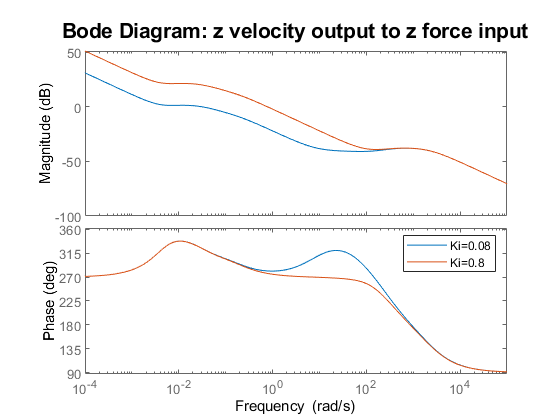

% bode diagram
figure('DefaultAxesFontSize',14)
hold on
bode(dyn_model_ss(2)) % only vz/fz
bode(dyn_model_ss_1(2)) % only vz/fz
legend('Ki=0.08', 'Ki=0.8')
title('Bode Diagram: z velocity output to z force input')

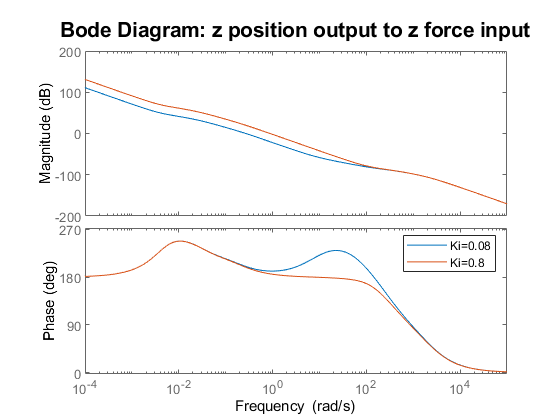

% Bode diagram for the position
s = tf('s');
figure('DefaultAxesFontSize',14)
hold on
bode(tf(dyn_model_ss(2))/s) 
bode(tf(dyn_model_ss_1(2))/s) 
legend('Ki=0.08', 'Ki=0.8')
title('Bode Diagram: z position output to z force input')

## Comparison with simulink simulation

load linsys_no_secondary_ctrl_2020.mat
ss_simulink = minreal(linsys1(2));

3 states removed.


%load linear_tf_analytical_approach.mat % previous analytical approach
ss_analytic = minreal(dyn_model_ss(2));

5 states removed.


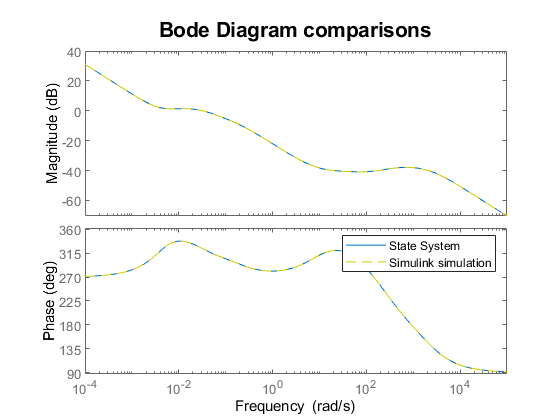

%tf_analytic = -minreal(Hz_youBot);

figure('DefaultAxesFontSize',14)
hold on
bode(ss_analytic) 
bode(ss_simulink, 'y--')
legend('State System', 'Simulink simulation')
title('Bode Diagram comparisons')

% 
figure('DefaultAxesFontSize',14)
hold on
bode(minreal(ss_analytic*s)) 

3 states removed.


bode(minreal(ss_simulink*s),'y--')

3 states removed.


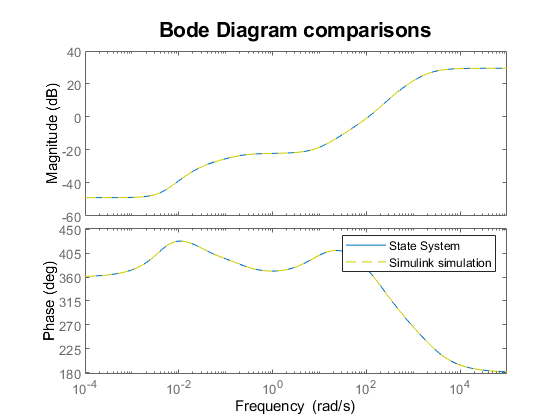

legend('State System', 'Simulink simulation')
title('Bode Diagram comparisons')

% DC gain comparison
DC_gain = dcgain(minreal(ss_analytic*s))

3 states removed.


DC_gain = 0.0036

## Conclusion

The linear analysis done here brings the same results as the simulink linear analysis. The previous linear analysis that was attempted without state representation, and with a simplified assumption for the linearisation of the control (inverse jacobian notably) gives some deviation with a globaly equivalent behaviour. The differences might be explained by the approximation of the assumption. For the rest of the analysis, the current linerisation done here will bne kept.

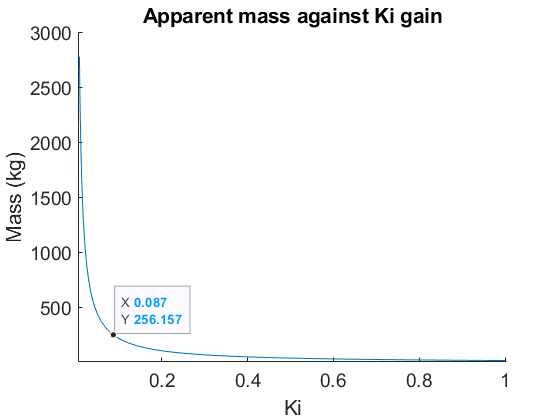

% Variation of Ki
answer = questdlg('Do you want to execute the conclusion section ? This might takes few minutes.', ...
	'Warning conclusion section', ...
	'Yes','No','No');
if strcmp("Yes", answer)
    Kiz = 1e-3*(8:5:1000);
    Kpz = 0.015*ones(size(Kiz));
    DC_gains = zeros(size(Kiz));
    cz0i = [Kpz;Kiz];
    h = waitbar(0,'Initializing waitbar...');
    % linearized matrices
    Ai1 = subs(A,[state;in],[state0;in0]);
    Bi1 = subs(B,[state;in],[state0;in0]);
    Ci1 = subs(C,[state;in],[state0;in0]);
    Di1 = subs(D,[state;in],[state0;in0]);
    for ii = 1:length(Kiz)
        Ai = double(subs(Ai1,cz,cz0i(:,ii)));
        Bi = double(subs(Bi1,cz,cz0i(:,ii)));
        Ci = double(subs(Ci1,cz,cz0i(:,ii)));
        Di = double(subs(Di1,cz,cz0i(:,ii)));
        % state system
        dyn_model_ss_i = ss(Ai,Bi,Ci,Di);
        DC_gains(ii) = dcgain(minreal(dyn_model_ss_i(2)*s, [], false)); % false delete verbose from minreal func
        waitbar(ii/1000,h,sprintf('%.1f%%...',0.1*ii))
    end 
    close(h)
    figure('DefaultAxesFontSize',14)
    hold on
    plot(Kiz,1./DC_gains)
    plot(Kiz(16),1./DC_gains(16), 'p')
    xlabel('Ki')
    ylabel('Mass (kg)')
    title('Apparent mass against Ki gain')
end

Last update 06/01/2021, Vincent FORTINEAU, PhD. student at L2S, Université Paris-Saclay, France